# Residual Supply Index estimation of selected market participants

## Import the data

### Import the list of selected generators

load("../model_output/mat_files/cleanedSel4QMCSeasons.mat")

### Import selected datetime and price

load("../model_output/mat_files/PriceOrigFiltSeasons.mat");

### Import ISONE hourly demand data

% Import ISONE hourly demand data in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

### Import generation capacity and Lerner Index data

load("../model_output/mat_files/partCapTableSeasons.mat");
load("../model_output/mat_files/LernerPolyfitSeasons.mat")

## Calculate MS, RSI, price upper bound and LI upper bound of selected market participants

selMSRSITables = cell(4, 4);
sel4PartCap = zeros(4, 4);
for n=1:4
    partID = sel4PartIDs(n);
    for s=1:4
        cleanedDates = sel4CleanedQMCSeason{n, s}.Date;
        cleanedHours = sel4CleanedQMCSeason{n, s}.Hour;
        cleanedMC = sel4CleanedQMCSeason{n, s}.MCMarket;
        cleanedAwarded = sel4CleanedQMCSeason{n, s}.MCMarket;
        selMS = zeros(size(cleanedHours));
        selRSI = zeros(size(cleanedHours));
        selLIUpper = zeros(size(cleanedHours));
        selPriceUpper = zeros(size(cleanedHours));
        selPrice = zeros(size(cleanedHours));
        selLI = zeros(size(cleanedHours));
        capTableOneSeason = partCapTableSeasons{s};
        selPartCap = capTableOneSeason(capTableOneSeason.PartID == partID, :).Capacity;
        selPartOtherCap = capTableOneSeason(capTableOneSeason.PartID == partID, :).OtherCap;
        sel4PartCap(n, s) = selPartCap;
        priceTable = selPriceSeasons{s};
        for dt=1:size(cleanedHours)
            Date = cleanedDates(dt);
            Hour = cleanedHours(dt);
            hourlyDemand = demandAll(demandAll.Date == Date, :);    
            selHourDemand = hourlyDemand(hourlyDemand.Hour == Hour, :).DayAheadDemand;
            % Calcualte market share
            selMS(dt) = min(selPartCap, selHourDemand)/selHourDemand;
            % Calculate residual supply index
            selRSI(dt) = selPartOtherCap/selHourDemand;
            % Get price data
            selPrice(dt) = priceTable(priceTable.Date == Date & priceTable.Hour == Hour, :).averageLMP;
            % Calculate Lerner Index
            selLI(dt) = (selPrice(dt) - cleanedMC(dt))/selPrice(dt);            
            % Calculate Lerner Index upper bound
            selLIUpper(dt) = selMS(dt)/(selMS(dt) + selRSI(dt) - 1);
            % Calculate price upper bound
            selPriceUpper(dt) = (1 + (selMS(dt)/(selRSI(dt) - 1)))*cleanedMC(dt);            
        end
        selMSRSITables{n, s} = table(cleanedDates, cleanedHours, cleanedAwarded, cleanedMC, selMS, selRSI, selLI, selLIUpper, selPrice, selPriceUpper);
        selMSRSITables{n, s}.Properties.VariableNames = ["Date", "Hour", "Awarded", "MC", "MS", "RSI", "LI", "LIUpper", "Price", "PriceUpper"];
    end   
end

### Calculate statistics of the cleaned MC data

selMCSeasonalMedian = zeros(4, 4);
selMSSeasonalMedian = zeros(4, 4);
selRSISeasonalMedian = zeros(4, 4);
for n=1:4
    for s=1:4
        selTableOneSeason = selMSRSITables{n, s};
        selMCSeasonalMedian(n, s) = median(selTableOneSeason.MC);
        selMSSeasonalMedian(n, s) = median(selTableOneSeason.MS);
        selRSISeasonalMedian(n, s) = median(selTableOneSeason.RSI);
    end    
end

### Plot price vs RSI of selected market participants in 4 seasons

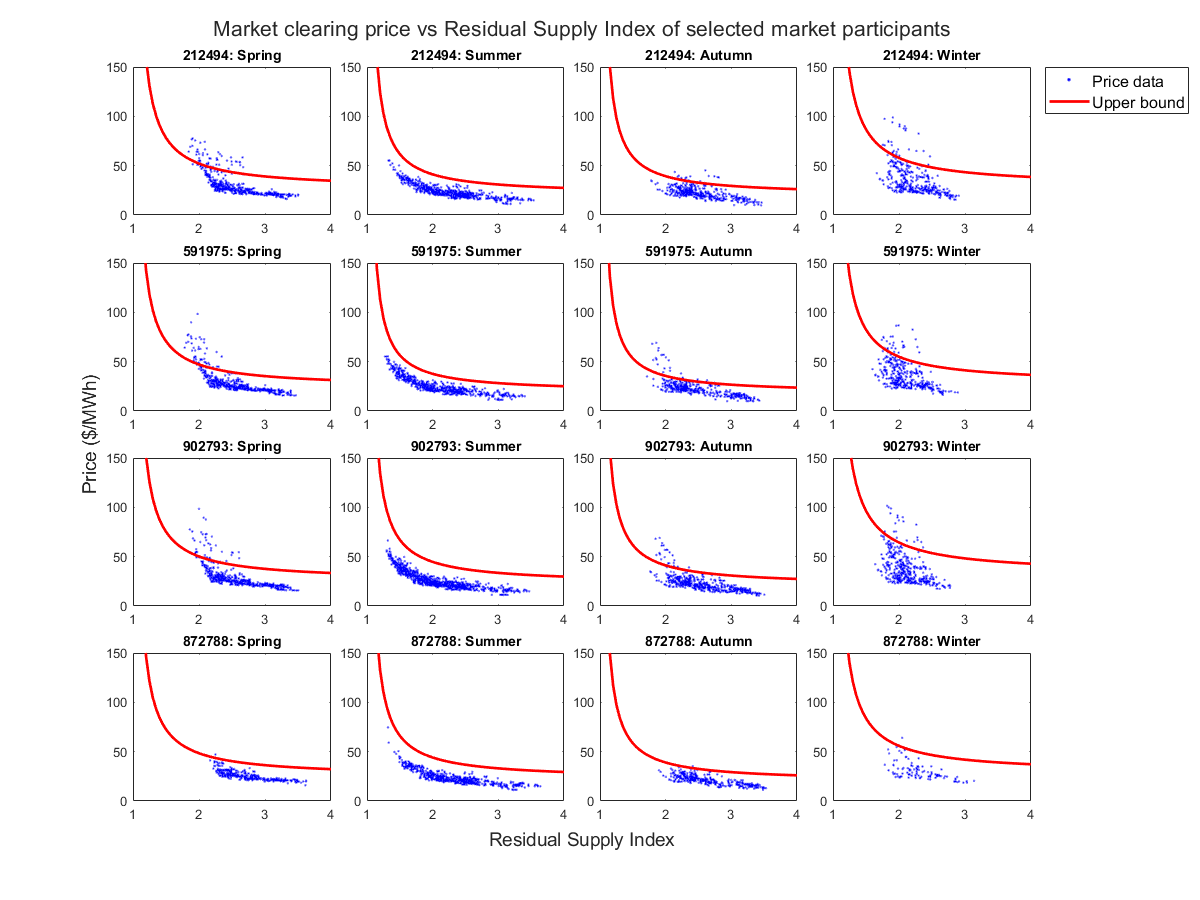

RS4Plot = 1:0.05:4;
LMCSeasons = selMCSeasonalMean;
Seasons = ["Spring"; "Summer"; "Autumn"; "Winter"];
t = tiledlayout(4,4,"TileSpacing","compact");
for n=1:4
    for s=1:4
    nexttile;
    hold on;
    y = scatter(selMSRSITables{n, s}.RSI, selMSRSITables{n, s}.Price, 10, "b.");
    priceUpper = (RS4Plot./(RS4Plot-1))*LMCSeasons(n,s);
    b = plot(RS4Plot, priceUpper, 'r-', "LineWidth",2);
    hold off; box on;
    txt = sprintf("%s: %s", sel4PartIDs(n), Seasons(s));
    title(txt, "FontSize", 14);
    axis([1, 4, 0, 150]);
    if (s==4) && (n==1)
        legend([y, b],["Price data", "Upper bound"], "Location","bestoutside", "FontSize", 12);
    end
    end
end
xlabel(t, "Residual Supply Index", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize",  14);
title(t, "Market clearing price vs Residual Supply Index of selected market participants", "FontSize",  16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/RSISel.png");

selMCSeasonalMedian

selMCSeasonalMedian =        22.905       19.565       19.057       24.435
       20.851       18.315       18.091       24.963
       22.328       21.054       19.777       27.913
        23.56       20.902       19.662       25.759


sel4PartCap

sel4PartCap =          1974         1891         1920       2089.5
         2965         3052         2969         3282
       2658.5       2480.4       2145.3       2547.5
          942         1010         1068          817


selMSSeasonalMedian

selMSSeasonalMedian =       0.16248      0.14028      0.15589      0.15027
      0.25325      0.21427      0.23819      0.23085
      0.22627      0.16645      0.17777      0.17727
     0.080952     0.073874     0.087273     0.058913


selRSISeasonalMedian

selRSISeasonalMedian =        2.4936       2.2536       2.4642       2.1704
       2.5029       2.0512       2.3506       2.0389
       2.5203        1.999       2.4962       2.0682
       2.6922       2.2864       2.5497        2.268


## Price vs price upper bound plot

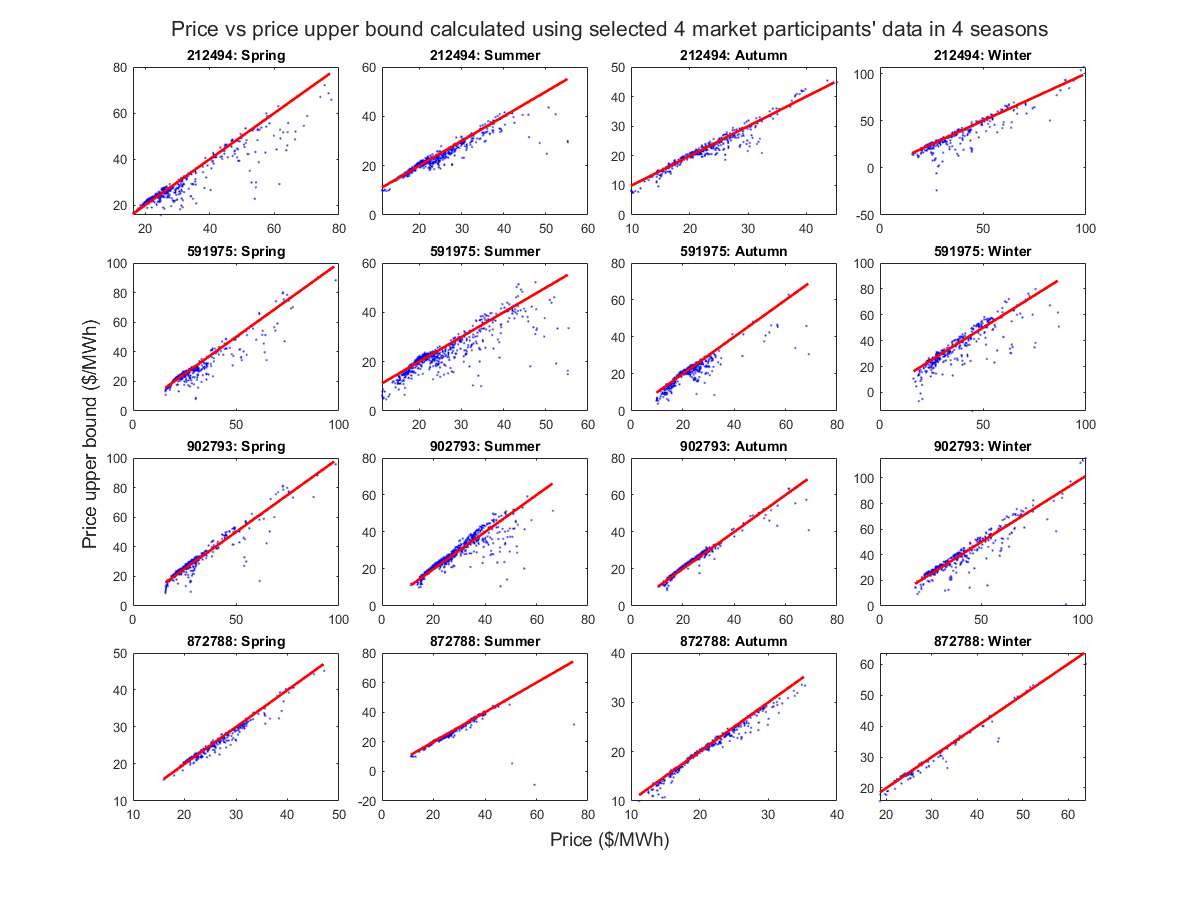

t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        hold on;
        scatter(selMSRSITables{n, s}.Price, selMSRSITables{n, s}.PriceUpper, 10, "b.");
        price4Plot = min(selMSRSITables{n, s}.Price):max(selMSRSITables{n, s}.Price);
        plot(price4Plot, price4Plot, 'r-', "LineWidth", 2);
        hold off; box on;
        txt = sprintf("%s: %s", sel4PartIDs(n), Seasons(s));
        title(txt, "FontSize", 14);
    end
end
xlabel(t, "Price ($/MWh)", "FontSize", 14);
ylabel(t, "Price upper bound ($/MWh)", "FontSize",  14);
title(t, "Price vs price upper bound calculated using selected 4 market participants' data in 4 seasons", "FontSize",  16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/priceUpper.png");

## Lerner Index vs Lerner Index upper bound plot

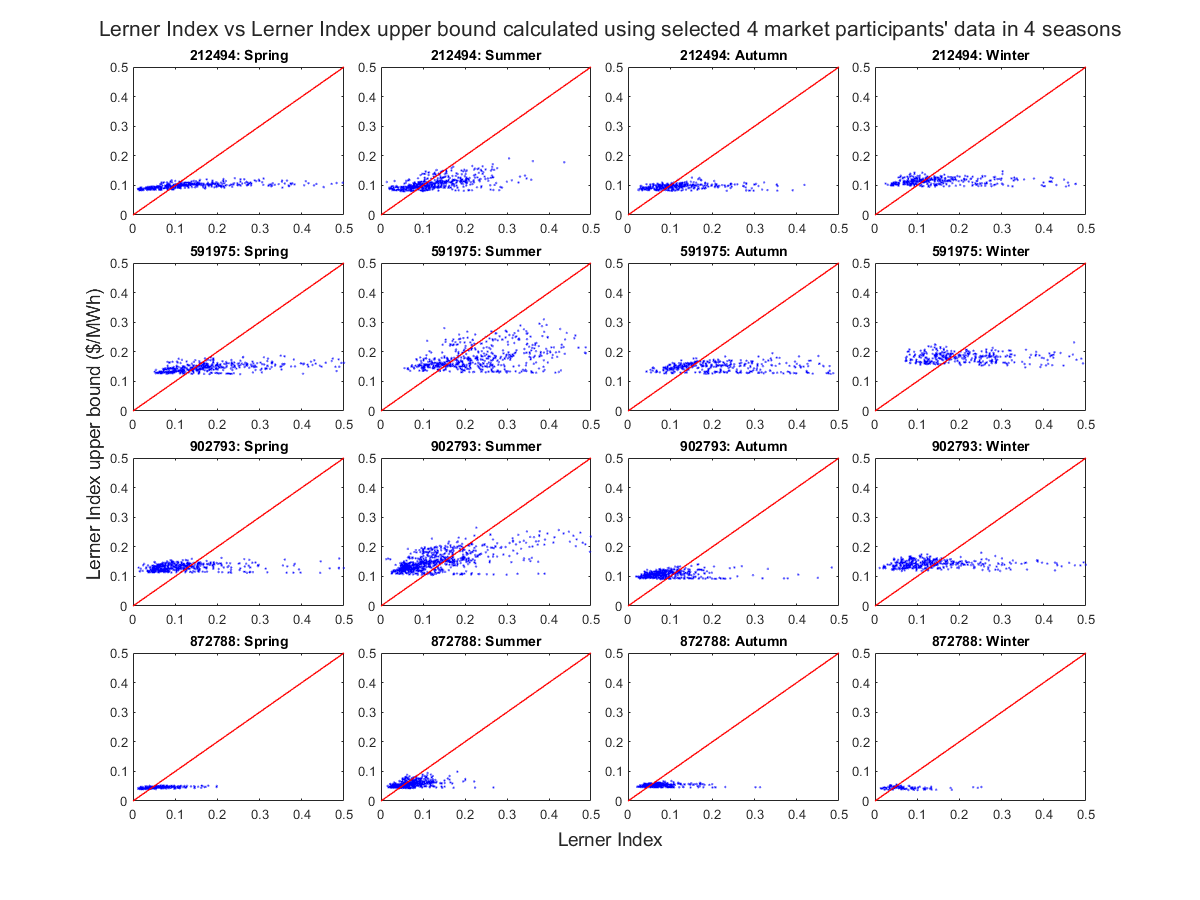

t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        hold on;
        scatter(selMSRSITables{n, s}.LI, selMSRSITables{n, s}.LIUpper, 10, "b.");
        xlim([0, 0.5]);
        plot(0:1, 0:1, 'r-', "LineWidth", 1);
        hold off; box on;
        txt = sprintf("%s: %s", sel4PartIDs(n), Seasons(s));
        title(txt, "FontSize", 14);
    end
end
xlabel(t, "Lerner Index", "FontSize", 14);
ylabel(t, "Lerner Index upper bound ($/MWh)", "FontSize",  14);
title(t, "Lerner Index vs Lerner Index upper bound calculated using selected 4 market participants' data in 4 seasons", "FontSize",  16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/LIUpper.png");